# Assignment 6 in OptReg

#### By Alexander Rambech

### Task 1

**a) **

From Newtons second law $F = ma$, where $F = u$ and $m = 1$, we know that $a = u$. Writing this on state space form we have that:

- 
$$x_1 = x$$


- 
$$x_2  = \dot x = v$$


- 
$$\dot x_1 = x_2$$


- 
$$\dot x_2 = \ddot x = a$$


where $x$, $v$ and $a$ are position, velocity and acceleration, respectively. On continuous state space form this is:

- 
$$\dot x = \left[\matrix{\dot x_1 \cr \dot x_2  }\right] = \left[\matrix{0 & 1 \cr 0 & 0}\right]  \left[\matrix{x_1 \cr x_2  }\right]  + \left[\matrix{0 \cr  1}\right]  u$$


**b)**

By exact descretization we have that the descrete system matrix and vector $A$ and $b$ are given by:

- $A = e^{A_c T}$ and $b = \left( \int_0^T  e^{A_c \tau} d \tau\right)b_c$

where $ e^{A_c T}$ is given by $ e^{A_c T} = \sum_{k=0}^\infty A^k_cT^k$, where the first element in the series is defined as the identity matrix. We don't care about the higher terms and calculate the matrix exponential as:

- 
$$ e^{A_c T} = I + A_cT = I + A_c\cdot 0.5 = \left[\matrix{1 & 0.5 \cr 0 & 1} \right] = A$$


and the $b$ vector as:

- 
$$b = \left( \int_0^T  e^{A_c \tau} d \tau\right)b_c = \left( \int_0^T \left[\matrix{1 & \tau \cr 0 & 1} \right]  \right)b_c =  \left[\matrix{T& \frac{1}{2}T^2 \cr c & T}\right]  \left[\matrix{0 \cr 1} \right]  = \left[\matrix{\frac{1}{2}T^2 \cr T} \right]  = \left[\matrix{0.125 \cr 0.5} \right] $$


**c)**

For a finite-horizon LQR the Riccati equation is given by:

- 
$$P_t = Q_t + A^T_t P_{t+1}(I + B_tR_t^{-1}B_t^TP_{t+1} )^{-1}A_t ,\ \text{ for} \ t= 0, \dots,N-1$$


where $P_N = Q_N$. By using this, the LQR feedback gain can be found:

- 
$$K_t = R_t^{-1}B_t^TP_{t+1}(I + B_tR_t^{-1}B_t^TP_{t+1} )^{-1}A_t, \ \text{ for}\ t= 0, \dots,N-1$$


using this we get the state feedback:

- 
$$u_t = -K_tx_t$$


A sketch of the controller is given below

**d)**

We know that if $N \to \infty$that the system becomes an infinite horizon LQR with a corresponding Riccati equation and way of finding $K$:

- 
$$P = Q + A^T P ( I + BR^{-1}B^TP)^{-1} A$$


- 
$$K = R^{-1}B^TP(I + BR^{-1}B^TP )^{-1}A$$


we therefore choose to omit the horizon in our implementation of **dlqr**.

% Initialising system 
A = [1 0.5; 0 1];
b = [0.125; 0.5];

Q  = [2 0; 0 2];
R = 2;

% We divide by two because this hasn't been done
Q = Q/2;
R = R/2;

% Finding K and P
[K, P, CLP] = dlqr(A, b, Q, R);
P

P =     4.0350    2.0616
    2.0616    4.1438


CLP

CLP =    0.6307 + 0.1628i
   0.6307 - 0.1628i


We see that we get the expected result. The closed-loop eigenvalues are $\lambda = 0.63 \pm 0.16i$ which is less than one and the closed-loop system is therefore stable.

**e)**

In general LQR is stable if the matrices $(A, B)$ are stabilizable and $(A, D)$ are detectable. Here $Q = D^TD$. A system is stabilizable if it is controllable and detectable if its observable.

### Task 2

**a)**

We have seen the Riccati equation for infinite-horizon LQR earlier in this assignment, the scalar version of this is given by:

- 
$$p = q + ap\frac{1}{1 + b\frac{1}{r}bp}a =q + \frac{a^2pr}{r + b^2p} $$


for $q = 2$, $a=3$, $b = 2$ and $r = 1$ we have:

- 
$$p = 2 + \frac{9\cdot p}{1 + 4\cdot p}  \Rightarrow p^2 -4p -\frac{1}{2}$$


roots([1 -4 -0.5])

ans =     4.1213
   -0.1213


Since $p$ must be positive definite we have that $p = 4.12$.

**b)**

The optimal feedback coefficient $k$ is given by:

-    
$$k = \frac{bpa}{r+pb^2} = \frac{2\cdot 4.12 \cdot 3}{1 + 4.12 \cdot 4} \approx \sqrt2$$


This gives and optimal feed back term $u = -\sqrt2x$.

**c)**

This is the same as for the finite time horizon case if the system is detectable and stabilizable, then the closed-loop solution will be asymptotically stable for a linear system.

### Task 3

**a)**

Here I choose to use the code provided on Blackboard:

%% Assignment 5, Problem 1 f)
%  Solves the QP with quadprog, with lower and upper bounds on u.
%  Tor Aksel N. Heirung, April 2013.

% System matrices
A = [0     0      0    ;
     0     0      1    ;
     0.1  -0.79   1.78];
B = [1 0 0.1]';
C = [0 0 1];

x0 = [0 0 1]'; % Initial state

N = 30; % Length of time horizon
nx = size(A,2); % nx: number of states (equals the number of rows in A)
nu = size(B,2); % nu: number of controls (equals the number of rows in B)

% Cost function
I_N = eye(N);
Qt = 2*diag([0, 0, 1]);
Q = kron(I_N, Qt);
Rt = 2*1;
R = kron(I_N, Rt);
G = blkdiag(Q, R);

% Equality constraint
Aeq_c1 = eye(N*nx);                         % Component 1 of A_eq
Aeq_c2 = kron(diag(ones(N-1,1),-1), -A);    % Component 2 of A_eq
Aeq_c3 = kron(I_N, -B);                     % Component 3 of A_eq
Aeq = [Aeq_c1 + Aeq_c2, Aeq_c3];

beq = [A*x0; zeros((N-1)*nx,1)];

% Inequality constraints
x_lb = -Inf(N*nx,1);    % Lower bound on x
x_ub =  Inf(N*nx,1);    % Upper bound on x
u_lb = -ones(N*nu,1);   % Lower bound on u
u_ub =  ones(N*nu,1);   % Upper bound on u
lb = [x_lb; u_lb];      % Lower bound on z
ub = [x_ub; u_ub];      % Upper bound on z

% Solving the equality- and inequality-constrained QP with quadprog
opt = optimset('Display','notify', 'Diagnostics','off', 'LargeScale','off', 'Algorithm', 'interior-point-convex');
[z,fval,exitflag,output,lambda] = quadprog(G,[],[],[],Aeq,beq,lb,ub,[],opt);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


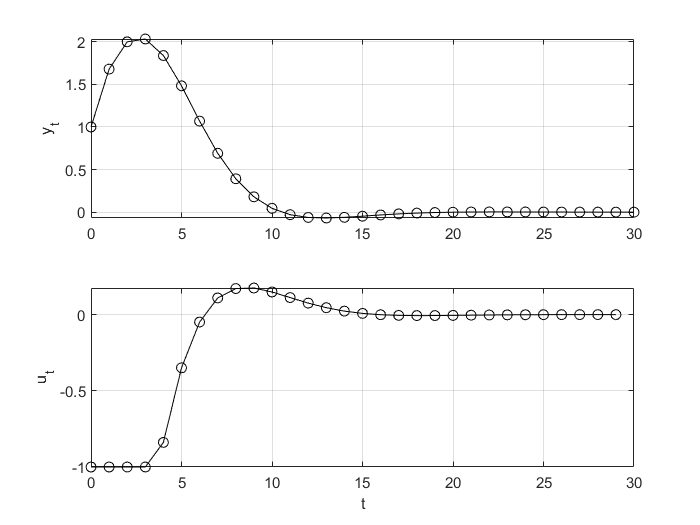


% Extracting variables
y = [x0(3); z(nx:nx:N*nx)]; % y = x3
u = z(N*nx+1:N*nx+N*nu);    % Control
% Time vector
t = 1:N;

% Plot optimal trajectory
figure(4);
subplot(2,1,1);
plot([0,t],y,'-ko'); % Plot on 0 to N
grid('on');
ylabel('y_t')
subplot(2,1,2);
plot(t-1,u,'-ko'); % Plot on 0 to N-1
grid('on');
xlabel('t');
ylabel('u_t');

**b)**

% Previous code modified
clear all;

% System matrices
A = [0     0      0    ;
     0     0      1    ;
     0.1  -0.79   1.78];
B = [1 0 0.1]';
C = [0 0 1];

x0 = [0 0 1]'; % Initial state

N = 30; % Length of time horizon
n_pieces = 6;
samples_in_block = N/n_pieces;
nx = size(A,2); % nx: number of states (equals the number of rows in A)
nu = size(B,2); % nu: number of controls (equals the number of rows in B)

% Cost function
I_N = eye(N);
Qt = 2*diag([0, 0, 1]);
Q = kron(I_N, Qt);
Rt = 2*1;
R = kron(samples_in_block*eye(n_pieces), Rt);
G = blkdiag(Q, R);

% Equality constraint
Aeq_c1 = eye(N*nx);                         % Component 1 of A_eq
Aeq_c2 = kron(diag(ones(N-1,1),-1), -A);    % Component 2 of A_eq
Aeq_c3 = kron(kron(eye(n_pieces),ones(samples_in_block,1)), -B);                     % Component 3 of A_eq
Aeq = [Aeq_c1 + Aeq_c2, Aeq_c3];
beq = [A*x0; zeros((N-1)*nx,1)];

size(Aeq)

ans =     90    96


size(G)

ans =     96    96



% Inequality constraints
x_lb = -Inf(N*nx,1);    % Lower bound on x
x_ub =  Inf(N*nx,1);    % Upper bound on x
u_lb = -ones(N*nu,1);   % Lower bound on u
u_ub =  ones(N*nu,1);   % Upper bound on u
lb = [x_lb; u_lb];      % Lower bound on z
ub = [x_ub; u_ub];      % Upper bound on z

% Solving the equality- and inequality-constrained QP with quadprog
opt = optimset('Display','notify', 'Diagnostics','off', 'LargeScale','off', 'Algorithm', 'interior-point-convex');
[z,fval,exitflag,output,lambda] = quadprog(G,[],[],[],Aeq,beq,lb,ub,[],opt);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


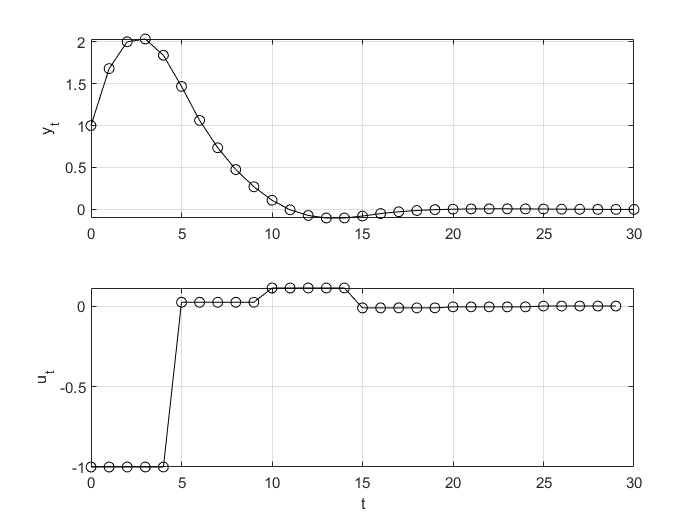


% Extracting variables
y = [x0(3); z(nx:nx:N*nx)]; % y = x3
u_temp = z(N*nx+1:N*nx+n_pieces*nu);    % Control
u = kron(eye(n_pieces),ones(samples_in_block,1))*u_temp;
% Time vector
t = 1:N;

% Plot optimal trajectory
figure(5);
subplot(2,1,1);
plot([0,t],y,'-ko'); % Plot on 0 to N
grid('on');
ylabel('y_t')
subplot(2,1,2);
plot(t-1,u,'-ko'); % Plot on 0 to N-1
grid('on');
xlabel('t');
ylabel('u_t');


output

output = struct with fields:
            message: '↵Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.594871e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.285018e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 8.107305e-14, is less than options.ConstraintTolerance = 1.000000e-08.↵↵'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.0019e-09
    constrviolation: 1.3089e-13
         iterations: 5
       linearsolver: 'dense'
       cgiterations: []


This works as inteded and iti is clear that we have fewer values for $u$. This seems to have little effects on the system that is being controlled as the plots for **a) **and **b) **are very similar. quadprog does this in $5$ iterations.

**c)**

% Previous code modified
clear all;

% System matrices
A = [0     0      0    ;
     0     0      1    ;
     0.1  -0.79   1.78];
B = [1 0 0.1]';
C = [0 0 1];

x0 = [0 0 1]'; % Initial state

N = 30; % Length of time horizon
n_pieces = 6;
samples_in_block = [1; 1; 2; 4; 8; 14];
nx = size(A,2); % nx: number of states (equals the number of rows in A)
nu = size(B,2); % nu: number of controls (equals the number of rows in B)

% Cost function
I_N = eye(N);
Qt = 2*diag([0, 0, 1]);
Q = kron(I_N, Qt);
Rt = 2*1;
R = kron(samples_in_block.*eye(n_pieces), Rt);
G = blkdiag(Q, R);

% Equality constraint
ones_and_ones = blkdiag(ones(samples_in_block(1),1), ones(samples_in_block(2),1),ones(samples_in_block(3),1),ones(samples_in_block(4),1),ones(samples_in_block(5),1),ones(samples_in_block(6),1));
Aeq_c1 = eye(N*nx);                         % Component 1 of A_eq
Aeq_c2 = kron(diag(ones(N-1,1),-1), -A);    % Component 2 of 
Aeq_c3 = kron(ones_and_ones, -B);                     % Component 3 of A_eq
Aeq = [Aeq_c1 + Aeq_c2, Aeq_c3];
beq = [A*x0; zeros((N-1)*nx,1)];

size(Aeq)

ans =     90    96


size(G)

ans =     96    96



% Inequality constraints
x_lb = -Inf(N*nx,1);    % Lower bound on x
x_ub =  Inf(N*nx,1);    % Upper bound on x
u_lb = -ones(N*nu,1);   % Lower bound on u
u_ub =  ones(N*nu,1);   % Upper bound on u
lb = [x_lb; u_lb];      % Lower bound on z
ub = [x_ub; u_ub];      % Upper bound on z

% Solving the equality- and inequality-constrained QP with quadprog
opt = optimset('Display','notify', 'Diagnostics','off', 'LargeScale','off', 'Algorithm', 'interior-point-convex');
[z,fval,exitflag,output,lambda] = quadprog(G,[],[],[],Aeq,beq,lb,ub,[],opt);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


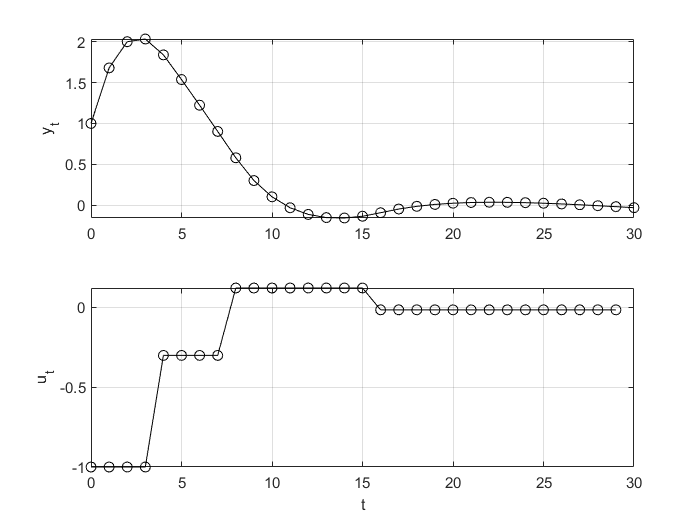


% Extracting variables
y = [x0(3); z(nx:nx:N*nx)]; % y = x3
u_temp = z(N*nx+1:N*nx+n_pieces*nu);    % Control
u = ones_and_ones*u_temp;
% Time vector
t = 1:N;

% Plot optimal trajectory
figure(6);
subplot(2,1,1);
plot([0,t],y,'-ko'); % Plot on 0 to N
grid('on');
ylabel('y_t')
subplot(2,1,2);
plot(t-1,u,'-ko'); % Plot on 0 to N-1
grid('on');
xlabel('t');
ylabel('u_t');


output

output = struct with fields:
            message: '↵Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.220434e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.930350e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 5.167955e-14, is less than options.ConstraintTolerance = 1.000000e-08.↵↵'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.9902e-08
    constrviolation: 2.8288e-13
         iterations: 5
       linearsolver: 'dense'
       cgiterations: []


We can still see little effects in the strep response of the system, but we see that this gives a higher resolution for the input and will handle systems experiencing larger or multiple pertubations better.